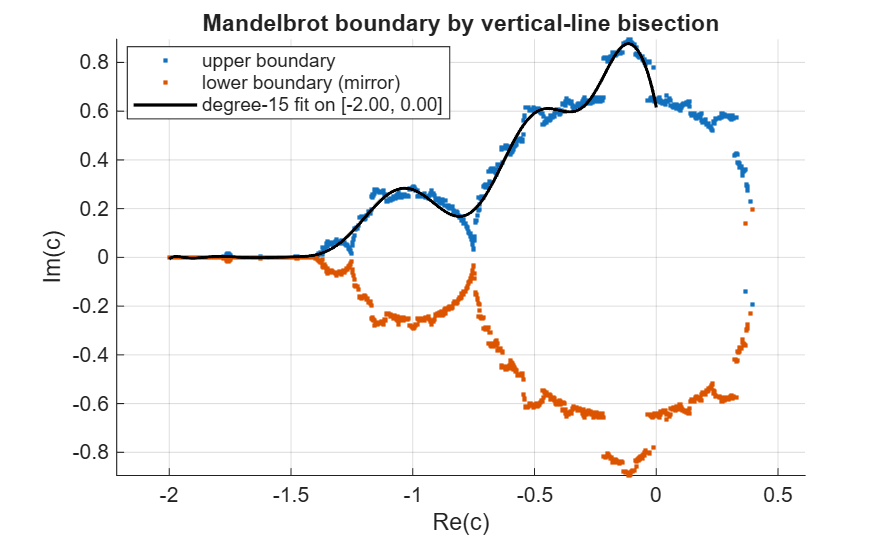

% 1. bisection algorism
n = 1400; % >=1000 samples
maxiter = 100; % Any point for |z|>2 before 100 iterations is not in the set
yspan = 2.5; % vertical search half-span to ensure bracketing
tol = 1e-6; % bisection tolerance
maxstep = 60;
poly = 15; % degree of polynomial per assignment
fit1 = -2.0; % left x-bound for fitting
fit2 =  0; % right x-bound for fitting
showBothHalves = true; % mirror the bounary across the real axis

xs = linspace (-2, 1, n);
ys = nan(size(xs)); % set upper boundary y(x), and NaN if not found.

for i = 1:n
    x = xs(i);
    fx = @(y) indicator_at_xy(x,y,maxiter); 
    % build the indicator fx(y) using the fractal test
    % produce a value of 1 for divergence (outside) and -1 for no divergence (inside)

    s = 0; % s lower bound point, y, assumed inside
    e = +yspan; % e upper bound point, y, assumed outside

    % If s is not inside, try to step downward until it is
    if fx(s) > 0 % >0 (+1) means outside, while we need keep it inside
        yy = s;
        while fx(yy) > 0 && yy > -yspan, yy = yy -0.1; end 
        % decreasing y by 0.1 until we either find fx(yy)=-1 or hit the bottom limit -yspan
        s = yy;
    end
    
    % similar with above, if e is not outside, try to step upward until it is
    if fx(e) < 0 % <0 (-1) means inside, while we need keep it outside
        yy = e;
        while fx(yy) < 0 && yy < yspan, yy = yy + 0.1; end
        % increasing y by 0.1 until we either find fx(yy)=+1 or hit the top limit yspan
        e = yy;
    end

    % if still not bracketing, skip this x and leave NaN
    if sign(fx(s)) * sign (fx(e)) >=0
        continue
    end

    ys(i) = bisection(fx, s, e, tol, maxstep); % bisection to locate boundary y(x)
end

figure; hold on
plot(xs, ys, '.', 'MarkerSize', 6, 'DisplayName','upper boundary');
if showBothHalves
    plot(xs, -ys, '.', 'MarkerSize', 6, 'DisplayName','lower boundary (mirror)');
end
axis equal
xlabel('Re(c)'); ylabel('Im(c)');
title('Mandelbrot boundary by vertical-line bisection');
legend('Location','best'); grid on


function it = fractal (c, maxiter) % complex point c (representing coordinates)
    % if not setting any number for iteration, it defult to 100
    if nargin < 2 || isempty (maxiter), maxiter = 100; end 
    z = 0;
    for k = 1:maxiter
        z = z^2 + c;
        if abs (z) > 2
            it = k;
            return
        end
    end
        it = 0; % if none escape, meaning no divergence, treat as inside
end

function fn = indicator_at_xy (x, y, maxiter)
    % mapping (-1, +1) using the fractal divergence test
    fn = (fractal(x + 1i * y, maxiter) > 0) * 2 - 1;  
end

function m = bisection(fn_f, s, e, tol, maxstep)
    % find a sign change of fn_f on [s,e]
    % if not setting any number, set defult
    if nargin < 4 || isempty(tol), tol = 1e-6; end
    if nargin < 5 || isempty(maxstep), maxstep = 60; end

    fs = sign(fn_f(s)); 
    fe = sign(fn_f(e));
    % 1 if greater than 0, -1 if less than 0, 0 if equal to 0
    if fs * fe > 0
        error('bisection: interval does not bracket a sign change');
    end

    for k = 1: maxstep
        m = 0.5*(s+e); % midpoint
        fm = sign(fn_f(m));
        if fm == 0 || 0.5*(e-s) < tol; break
        end
        if fm * fs < 0
            e = m; % update upper bound
            fe = fm;
        else
            s = m; % update lower bound
            fs = fm; 
        end
    end
end

% 2. polynomial fit y=f(x)
mask = ~isnan(ys) & xs >= fit1 & xs <= fit2;
xfit = xs(mask);
yfit = ys(mask);

% Fit a polynomial to the data points
p = polyfit(xfit, yfit, poly);

% Evaluate the polynomial at the x values for integration
xdense = linspace(fit1, fit2, 2000);
ypoly = polyval(p, xdense);

plot(xdense, ypoly, 'k-', 'LineWidth', 1.5, 'DisplayName', ...
    sprintf('degree-%d fit on [%.2f, %.2f]', poly, fit1, fit2));
legend('Location','best');


% 3. integration the curve to find the length
function l = poly_len(p, s, e)
    polyp = polyder (p); % derivative of polynomial p
    polys = @(x) sqrt (1+(polyval(polyp, x)).^2); % Arc length intergrand
    l = integral(polys, s, e, 'RelTol',1e-8, 'AbsTol',1e-10);
end
length_up = poly_len(p, fit1, fit2);
length_total = 2 * length_up;

fprintf('Upper-half arc length on [%.3f, %.3f]: %.8f\n', fit1, fit2, length_up);

Upper-half arc length on [-2.000, 0.000]: 2.70104020


fprintf('Estimated total length: %.8f\n', length_total);

Estimated total length: 5.40208039
